# Channel Matched Filter

% Downlink and Uplink
% Maximum Achievable Rate Possible
% Linear Formation and Rectangular Formation

## Global

clc;
clearvars;
M = [32, 64, 128, 256, 512];


## Precoder

P0 = [10.351946584497178,
    14.437626291321124,
    18.93298174254644,
    23.666771633646214,
    28.52988943765975];

P1 = [2.3952024838541206,
    3.933822295477039,
    6.300082527597143,
    9.510693729558058,
    13.417913986456567];

P2 = [1.0258949680366305,
    1.3892434416887962,
    1.9950783686599693,
    2.949826399624383,
    4.374172552582898];

P3 = [1.2138436584995913,
    1.4334816954751004,
    1.9314766593152053,
    2.5280039836255956,
    3.739104569617088];

P4 = [0.7455255545782148,
    0.777860248430156,
    0.8685067020631223,
    0.9568189671067542,
    1.1543811770203873];


## Equalizer

Q0 = [10.5812747753874,
    14.6529342326903,
    19.1397330110835,
    23.8687546024281,
    28.7293490792752];

Q1 = [2.68920731052828,
    4.20933293076410,
    6.55373641899724,
    9.74402384069214,
    13.6360196777208];

Q2 = [1.33993625261220,
    1.69760150980041,
    2.29455940385984,
    3.23671529061808,
    4.64506421467310];

Q3 = [1.52491040422338,
    1.74116667006222,
    2.23185581980243,
    2.82025588818673,
    4.01674762534109];

Q4 = [1.06414659121244,
    1.09594423407314,
    1.18509754781047,
    1.27197256569650,
    1.46638084932230];


## Plots

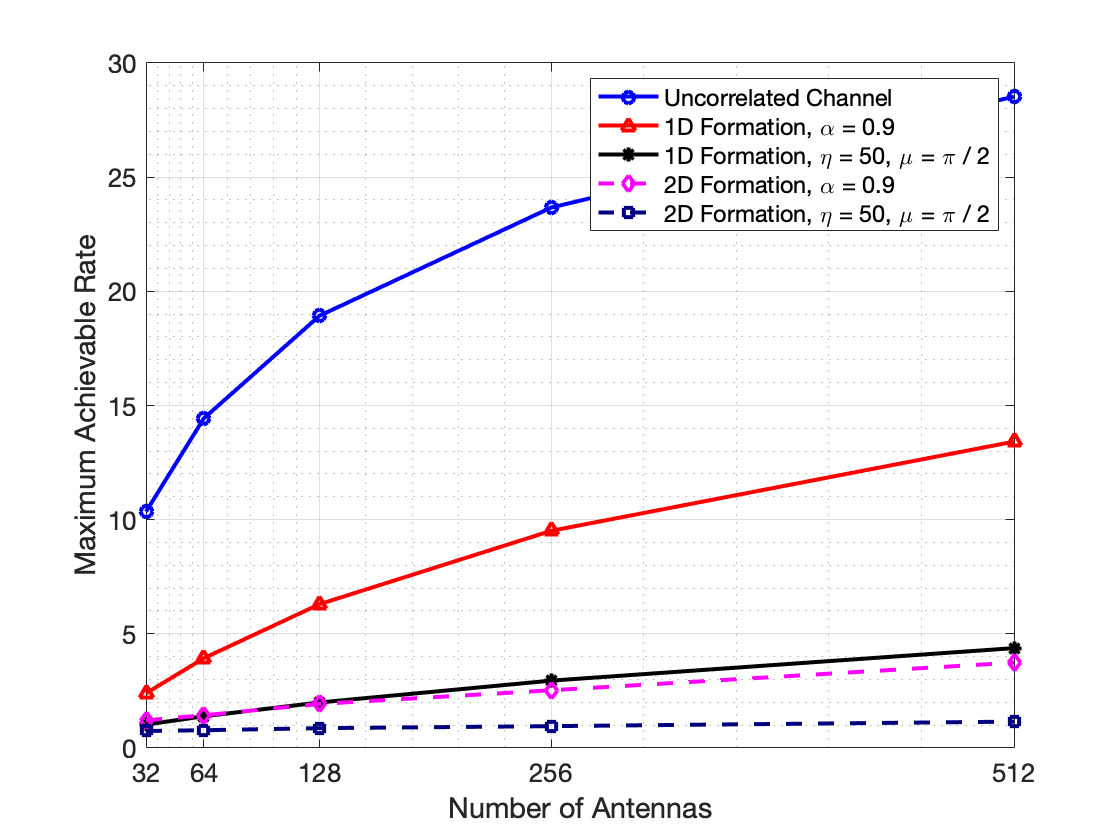

figure
plot(M, P0, '-bo', 'DisplayName', 'Uncorrelated Channel');
hold on;
plot(M, P1, '-r^', 'DisplayName', '1D Formation, \alpha = 0.9');
hold on;
plot(M, P2, '-k*', 'DisplayName', '1D Formation, \eta = 50, \mu = \pi / 2');
hold on;
plot(M, P3, '--md', 'DisplayName', '2D Formation, \alpha = 0.9');
hold on;
plot(M, P4, 'Color', [0, 0, 0.5], 'LineStyle', '--', 'Marker', 's', 'DisplayName', '2D Formation, \eta = 50, \mu = \pi / 2');
xlabel('Number of Antennas', 'fontsize', 15);
ylabel('Maximum Achievable Rate', 'fontsize', 15);
xticks(M);
xlim([M(1), M(5)]);
set(gca,'fontsize', 13);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
legend();
grid on;
grid minor;

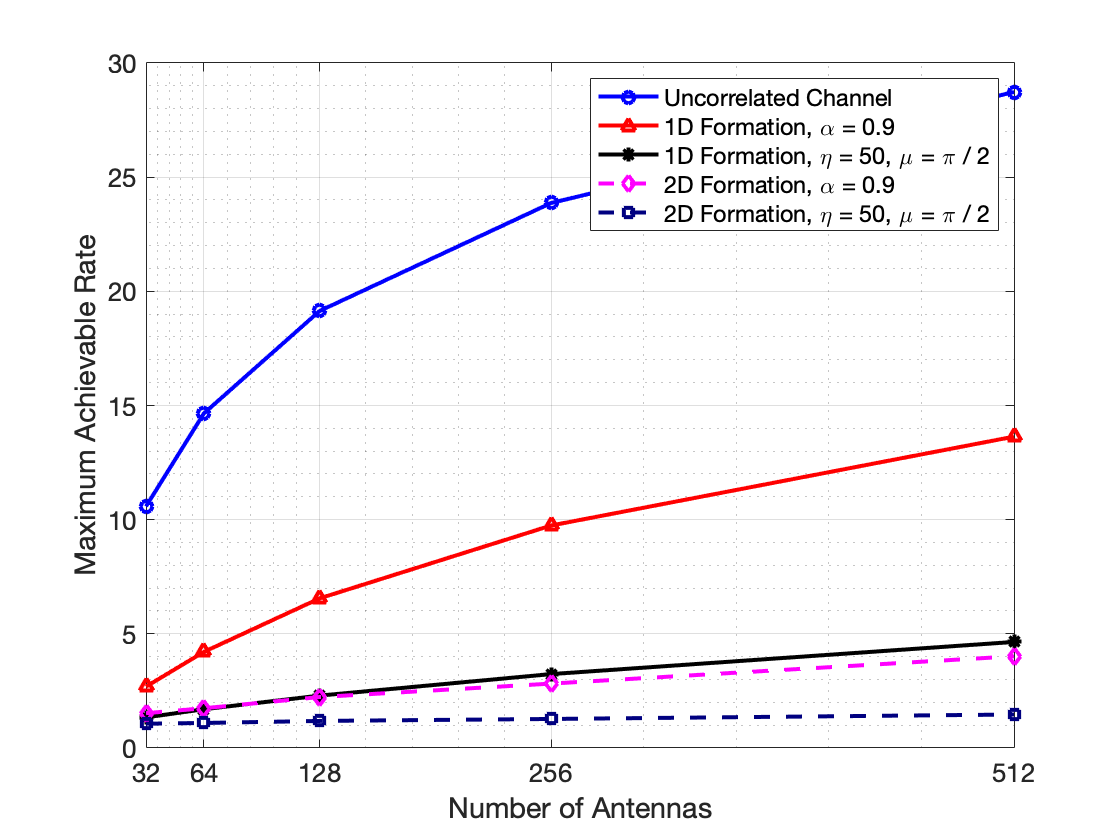


figure
plot(M, Q0, '-bo', 'DisplayName', 'Uncorrelated Channel');
hold on;
plot(M, Q1, '-r^', 'DisplayName', '1D Formation, \alpha = 0.9');
hold on;
plot(M, Q2, '-k*', 'DisplayName', '1D Formation, \eta = 50, \mu = \pi / 2');
hold on;
plot(M, Q3, '--md', 'DisplayName', '2D Formation, \alpha = 0.9');
hold on;
plot(M, Q4, 'Color', [0, 0, 0.5], 'LineStyle', '--', 'Marker', 's', 'DisplayName', '2D Formation, \eta = 50, \mu = \pi / 2');
xlabel('Number of Antennas', 'fontsize', 15);
ylabel('Maximum Achievable Rate', 'fontsize', 15);
xticks(M);
xlim([M(1), M(5)]);
set(gca,'fontsize', 13);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);
legend();
grid on;
grid minor;